# Principal Components Analysis

Script to implement Principal Component Analysis (PCA) based on Singular Value Decomposition (SVD)

Data matrix X is n x d (n = observations, d = dimensions)

Version log:

- v01: creation

## Data matrix X

% % As an example, X is (n x d) matrix of random integers ranging from 0 to N. 
% N = 10;
% n = 100;
% d = 40;
% X = randi(N, n, d);

% % Other example, X is (n x 4) matrix, 
% % where variables 1 and 2 are highly correlated 
% % and 3, 4 are also highly correlated
% N = 100;
% n = 150;
% 
% noise = (randi(20, 4, 1) + 1) ./ 2;
% 
% x1 = randi(N, n, 1) + noise(1) * randn(n, 1);
% x2 = -0.0065 * x1.^2 + 25 + noise(2) * randn(n, 1);
% figure
% scatter(x1, x2)
% xlabel('x1')
% ylabel('x2')
% 
% x3 = randi(N, n, 1) + noise(3) * randn(n, 1);
% x4 = 10 * abs(3 * x3).^(0.5) + noise(4) * randn(n, 1);
% figure
% scatter(x3, x4)
% xlabel('x3')
% ylabel('x4')
% 
% figure
% scatter(x1, x3)
% xlabel('x1')
% ylabel('x3')
% 
% X = [x1 x2 x3 x4];

% Other example IRIS data (150 observations, 4 measurements)
load('IRIS data.mat')
X = table2array(IRISdata(:, 1:4));

## Data matrix pre-processing

% Data matrix can be pre-processed by mean-centering and/or scaling by sd
preprocess_mean_centering = 1; % 1 = mean-centering activated, any other value = no mean-centering, 
preprocess_scaling_sd = 1; % 1 = scaling activated, any other value = no scaling, 

Xp = X; % Variable storing the pre-process X data matrix

if preprocess_mean_centering == 1
    disp('Mean-centering is activated')
    Xp = X - mean(X);
else
    disp('Mean-centering is deactivated')
end

Mean-centering is activated



if preprocess_scaling_sd == 1
    disp('Scaling by St Dev is activated')
    Xp = Xp ./ std(Xp);
else
    disp('Scaling by St Dev is deactivated')
end

Scaling by St Dev is activated


## PCA

[U, S, V] = svd(Xp, 'econ');

loadings = V;
eigenvalues = diag(S).^2;
scores = Xp * V;
explained_var = eigenvalues ./ sum(eigenvalues);
explained_var_cumul = cumsum(explained_var);

disp('PCA Loadings:'); V

PCA Loadings:


V =     0.5224   -0.3723    0.7210    0.2620
   -0.2634   -0.9256   -0.2420   -0.1241
    0.5813   -0.0211   -0.1409   -0.8012
    0.5656   -0.0654   -0.6338    0.5235


disp('PCA Scores:'); scores

PCA Scores:


scores =    -2.2570   -0.5040    0.1215    0.0230
   -2.0795    0.6532    0.2265    0.1029
   -2.3600    0.3174   -0.0513    0.0277
   -2.2965    0.5734   -0.0985   -0.0661
   -2.3808   -0.6725   -0.0214   -0.0373
   -2.0636   -1.5135   -0.0306    0.0044
   -2.4375   -0.0743   -0.3411   -0.0380
   -2.2264   -0.2468    0.0823   -0.0254
   -2.3341    1.0915   -0.1530   -0.0267
   -2.1814    0.4471    0.2457   -0.0398


disp('Eigenvalues:'); eigenvalues

Eigenvalues:


eigenvalues =   433.7119
  137.2619
   21.9556
    3.0705


disp('Explained Variance (for each PC):'); round(explained_var * 100, 2)

Explained Variance (for each PC):


ans =    72.7700
   23.0300
    3.6800
    0.5200


disp('Cumulative Explained Variance:'); round(explained_var_cumul * 100, 2)

Cumulative Explained Variance:


ans =    72.7700
   95.8000
   99.4800
  100.0000


## PCA 2D-plots

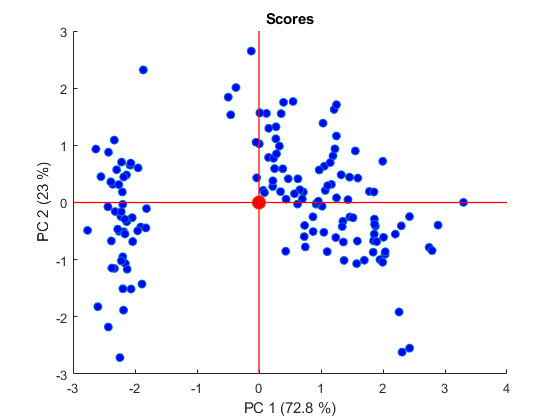

% Selection of PC scores/loadings to plot
PC_x = 1; % value (1 to  K) = PC to plot on x-axis
PC_y = 2; % value (1 to  K) = PC to plot on y-axis

% Score plot
figure
hold on
scatter(scores(:, PC_x), scores(:, PC_y), 'MarkerFaceColor','b')
scatter(0, 0, 100, 'MarkerFaceColor','r') % Materialize the origin
plot([0 0], ylim(), 'Color', 'r', 'LineWidth', 1)
plot(xlim(), [0 0], 'Color', 'r', 'LineWidth', 1)
xlabel(['PC ', num2str(PC_x), ' (', num2str(round(explained_var(PC_x) * 100, 1)), ' %)'])
ylabel(['PC ', num2str(PC_y), ' (', num2str(round(explained_var(PC_y) * 100, 1)), ' %)'])
title('Scores')
hold off

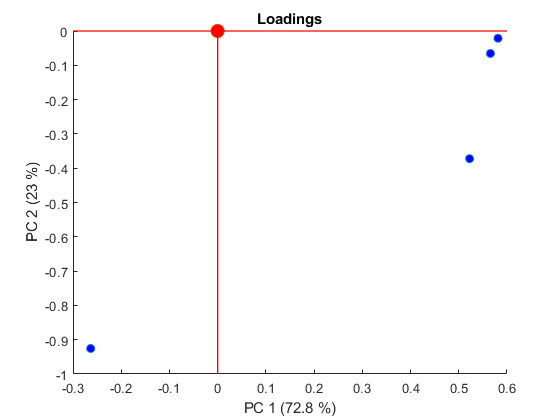


% Loading plot
figure
hold on
scatter(loadings(:, PC_x), loadings(:, PC_y), 'MarkerFaceColor','b')
scatter(0, 0, 100, 'MarkerFaceColor','r') % Materialize the origin
plot([0 0], ylim(), 'Color', 'r', 'LineWidth', 1)
plot(xlim(), [0 0], 'Color', 'r', 'LineWidth', 1)
xlabel(['PC ', num2str(PC_x), ' (', num2str(round(explained_var(PC_x) * 100, 1)), ' %)'])
ylabel(['PC ', num2str(PC_y), ' (', num2str(round(explained_var(PC_y) * 100, 1)), ' %)'])
title('Loadings')
hold off

## PCA 3D-plots

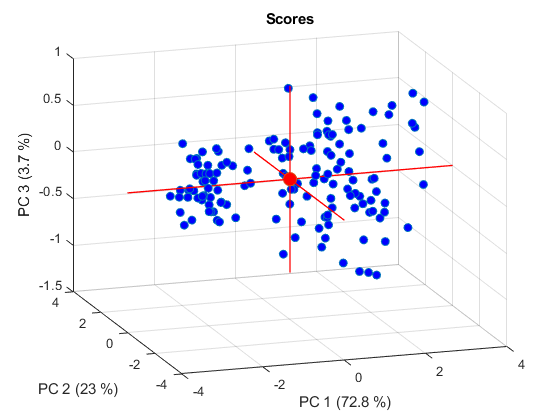

% Selection of PC scores/loadings to plot
PC_x = 1; % value (1 to  K) = PC to plot on x-axis
PC_y = 2; % value (1 to  K) = PC to plot on y-axis
PC_z = 3; % value (1 to  K) = PC to plot on z-axis

figure()
scatter3(scores(:, PC_x), scores(:, PC_y), scores(:, PC_z), 'MarkerFaceColor','b')
hold on
scatter3(0, 0, 0, 100, 'MarkerFaceColor','r') % Materialize the origin
plot3(xlim(), [0 0], [0 0], 'Color', 'r', 'LineWidth', 1)
plot3([0 0], ylim(), [0 0], 'Color', 'r', 'LineWidth', 1)
plot3([0 0], [0 0], zlim(), 'Color', 'r', 'LineWidth', 1)
xlabel(['PC ', num2str(PC_x), ' (', num2str(round(explained_var(PC_x) * 100, 1)), ' %)'])
ylabel(['PC ', num2str(PC_y), ' (', num2str(round(explained_var(PC_y) * 100, 1)), ' %)'])
zlabel(['PC ', num2str(PC_z), ' (', num2str(round(explained_var(PC_z) * 100, 1)), ' %)'])
title('Scores')
hold off

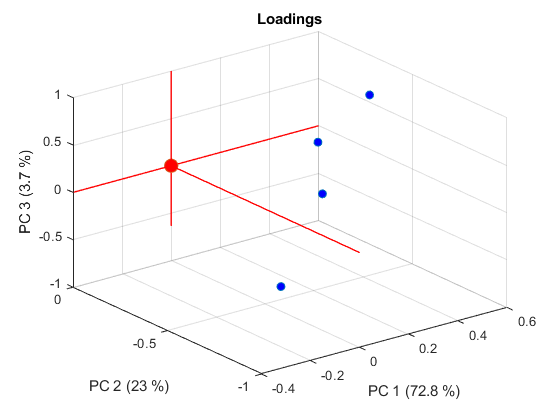


figure()
scatter3(loadings(:, PC_x), loadings(:, PC_y), loadings(:, PC_z), 'MarkerFaceColor','b')
hold on
scatter3(0, 0, 0, 100, 'MarkerFaceColor','r') % Materialize the origin
plot3(xlim(), [0 0], [0 0], 'Color', 'r', 'LineWidth', 1)
plot3([0 0], ylim(), [0 0], 'Color', 'r', 'LineWidth', 1)
plot3([0 0], [0 0], zlim(), 'Color', 'r', 'LineWidth', 1)
xlabel(['PC ', num2str(PC_x), ' (', num2str(round(explained_var(PC_x) * 100, 1)), ' %)'])
ylabel(['PC ', num2str(PC_y), ' (', num2str(round(explained_var(PC_y) * 100, 1)), ' %)'])
zlabel(['PC ', num2str(PC_z), ' (', num2str(round(explained_var(PC_z) * 100, 1)), ' %)'])
title('Loadings')
hold off